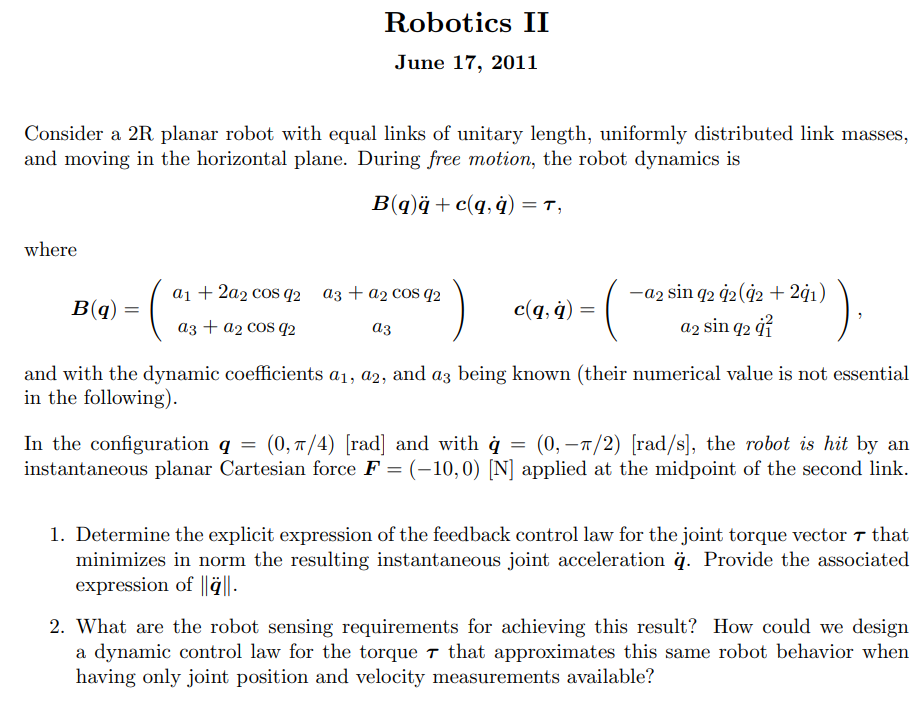

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,0];
R2Robot=['rr';'xx';sigmaD]

R2Robot = 3×2 char array
    'rr'
    'xx'
    '  '


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.l_=[1,1]';
z.dc=z.l_/2;
z.q=q;
z.q_=[0,pi/4]';
z.q_dot=q_dot;
z.q_dot_=[0,-pi/4]';
z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;


% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
[Pc,vc,w,T,Ti,M] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$


[C,cac,Csubs,S] = getCs(M,z.q,q_dot);

>> Getting  the Christoffel’sym. Might take a while...


Pc

$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

M

$$M = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

S

$$S = \left(\begin{array}{cc} -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

% g_q

## get dinamyc paramters

% % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
[All, dynamicParameters, a] = getDynamicParameters2([M,cac],q,[],2)

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$All = \left(\begin{array}{ccc} a_{1}+2\,a_{3}\,\cos\left(q_{2}\right) & a_{2}+a_{3}\,\cos\left(q_{2}\right) & -a_{3}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ a_{2}+a_{3}\,\cos\left(q_{2}\right) & a_{2} & a_{3}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{{\dot{q}}_{1}}^{2}\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right) \end{array}\right)$$

$$a = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$

% % [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],1)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)


% %
Msubs = All(:,1:n)

$$Msubs = \left(\begin{array}{cc} a_{1}+2\,a_{3}\,\cos\left(q_{2}\right) & a_{2}+a_{3}\,\cos\left(q_{2}\right)\\ a_{2}+a_{3}\,\cos\left(q_{2}\right) & a_{2} \end{array}\right)$$

cSubs = (All(:,n+1))

$$cSubs = \left(\begin{array}{c} -a_{3}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ a_{3}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

% % u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

**Collisions**

defining collisions link 1

% %
% % collide1=
rho=sym('rho',[2,1],'real')

$$rho = \left(\begin{array}{c} \rho_{1}\\ \rho_{2} \end{array}\right)$$

F=sym('F_',[3,1],'real')

$$F = \left(\begin{array}{c} F_{1}\\ F_{2}\\ F_{3} \end{array}\right)$$

F_=[-F(2),0,0]'

$$F\_ = \left(\begin{array}{c} -F_{2}\\ 0\\ 0 \end{array}\right)$$

z.collides=[struct('F',F_ ,'joint',2,'F_pos',l(2)/2),
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',1,'F_pos',z.q(1)-rho(1)),
%             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
%             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
            ];
z.collides(1)

ans = struct with fields:
        F: [3×1 sym]
    joint: 2
    F_pos: l2/2


computing colissions

z.prismatic_CoM_method=[2,2,1]

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
  

[Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: [2×1 double]
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: [2×1 double]
                  q_dot_: [2×1 double]
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: [1×1 struct]
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [2 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
  

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Vc\_T\_dot\_Fk = F_{2}\,\left({\dot{q}}_{1}\,\left(\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\sin\left(q_{1}\right)\right)+\frac{l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\right)$$

$$Tau\_c = \left(\begin{array}{c} F_{2}\,\left(\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\sin\left(q_{1}\right)\right)\\ \frac{F_{2}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}


>> Getting  the Christoffel’sym. Might take a while...
*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)$$

$$PE\_short = g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
                  U: {dc1*g0*m1*sin(q_1)  g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))}
          g_q_short: [2×1 sym]
           PE_short: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
                  U: {dc1*g0*m1*sin(q_1)  g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))}
          g_q_short: [2×1 sym]
           PE_short: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
                  U: {dc1*g0*m1*sin(q_1)  g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))}
          g_q_short: [2×1 sym]
           PE_short: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
                  U: {dc1*g0*m1*sin(q_1)  g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))}
          g_q_short: [2×1 sym]
           PE_short: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)


zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
                  U: {dc1*g0*m1*sin(q_1)  g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))}
          g_q_short: [2×1 sym]
           PE_short: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)


$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2
    Ti: [(q_dot_1^2*(m1*dc1^2 + I1))/2    (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: q_1 + q_2
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2
                     Ti: [(q_dot_1^2*(m1*dc1^2 + I1))/2    (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q

zout = struct with fields:
    J_c_collisions_: {[3×2 sym]}
                  C: {[2×2 sym]  [2×2 sym]}
                cac: [2×1 sym]
              Csubs: {[2×2 sym]  [2×2 sym]}
                  S: [2×2 sym]
                g_q: [2×1 sym]
                 PE: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
                  U: {dc1*g0*m1*sin(q_1)  g0*m2*(dc2*sin(q_1 + q_2) + l1*sin(q_1))}
          g_q_short: [2×1 sym]
           PE_short: g0*sin(q_1)*(dc1*m1 + l1*m2) + dc2*g0*m2*sin(q_1 + q_2)
      Pc_collisions: [3×1 sym]
      vc_collisions: [3×1 sym]
     J_c_collisions: {[3×2 sym]}
        Vc_T_dot_Fk: F_2*(q_dot_1*((l2*sin(q_1 + q_2))/2 + l1*sin(q_1)) + (l2*q_dot_2*sin(q_1 + q_2))/2)
              Tau_c: [2×1 sym]
                p_r: [2×1 sym]
                tau: [2×1 sym]
                  r: [2×1 sym]
                P_0: [2×1 sym]
       to_integrate: [2×1 sym]
     Pc_collisions_: [3×1 sym]
     vc_collisions_: [3×1 sym]
       Vc_T_dot_Fk_: -(pi*2^(1/2)*F_2)/16


% zout.g_q
zout.S

$$ans = \left(\begin{array}{cc} -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

zout.J_c_collisions_{:}

$$ans = \left(\begin{array}{cc} -\frac{\sqrt{2}}{4} & -\frac{\sqrt{2}}{4}\\ \frac{\sqrt{2}}{4}+1 & \frac{\sqrt{2}}{4}\\ 0 & 0 \end{array}\right)$$


zout.J_c_collisions{:}

$$ans = \left(\begin{array}{cc} -\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}-l_{1}\,\sin\left(q_{1}\right) & -\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\\ \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right) & \frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\\ 0 & 0 \end{array}\right)$$

zout.vc_collisions

$$ans = \left(\begin{array}{c} -{\dot{q}}_{1}\,\left(\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\sin\left(q_{1}\right)\right)-\frac{l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\\ {\dot{q}}_{1}\,\left(\frac{l_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\cos\left(q_{1}\right)\right)+\frac{l_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\\ 0 \end{array}\right)$$

zout.Vc_T_dot_Fk

$$ans = F_{2}\,\left({\dot{q}}_{1}\,\left(\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\sin\left(q_{1}\right)\right)+\frac{l_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\right)$$

zout.Tau_c

$$ans = \left(\begin{array}{c} F_{2}\,\left(\frac{l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}+l_{1}\,\sin\left(q_{1}\right)\right)\\ \frac{F_{2}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

zout.r

$$ans = \left(\begin{array}{c} r_{1}\\ r_{2} \end{array}\right)$$

zout.p_r

$$ans = \left(\begin{array}{c} {\dot{q}}_{2}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\right)+{\dot{q}}_{1}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2}\right)\\ {\dot{q}}_{2}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2}\right)+{\dot{q}}_{1}\,\left(m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\right) \end{array}\right)$$

zout.to_integrate

$$ans = \left(\begin{array}{c} r_{1}+\tau_{1}-g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)-{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)\\ r_{2}+\tau_{2}-{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)-{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right) \end{array}\right)$$

% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% 